# 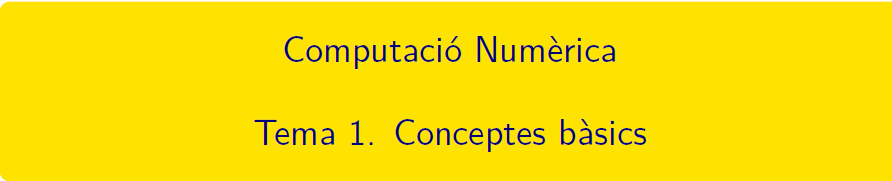

# MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

# Anàlisis de l'error

### Error absolut i error relatiu.

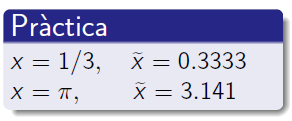

format short
x = 1/3; xa = 0.3333;
ea = abs(x-xa) 

ea = 3.3333e-05

er = ea/abs(x) 

er = 1.0000e-04

erp = er*100 

erp = 0.0100

format short
x = pi; xa = 3.141;
ea = abs(pi-3.141)
er = ea/abs(x)
erp = er*100

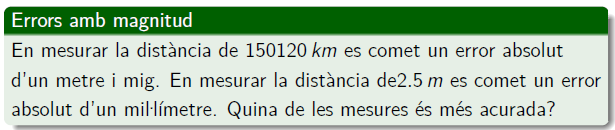

d1 = 150120;
ea1 = 1.5/1000;
d2 = 2.5;
ea2 = 1/1000;
er1 = ea1/abs(d1)

er1 = 9.9920e-09

er2 = ea2/abs(d2)

er2 = 4.0000e-04

% La mesura de la d1 és més acurada que d2

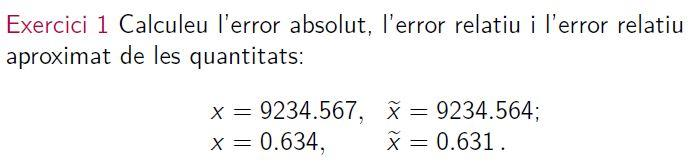

format short g
x = 9234.567; xa = 9234.564;
ea = abs(x-xa)

ea =         0.003


er = ea/abs(x)

er =    3.2487e-07


er_aprox = ea/abs(xa) 

er_aprox =    3.2487e-07


x = 0.634; xa = 0.631;
ea = abs(x-xa)

ea =         0.003


er = ea/abs(x)

er =     0.0047319


er_aprox = ea/abs(xa)

er_aprox =     0.0047544


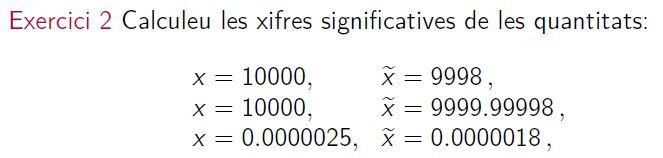

% 1
x = 10^4; xa = 9998;
er = abs(x-xa)/abs(x)

er =        0.0002


% 2
x = 10^4; xa = 9999.99998;
er = abs(x-xa)/abs(x)

er =         2e-09


% 3
x = 25/10^7; xa = 18/10^7;
er = abs(x-xa)/abs(x)

er =          0.28


### **Errors d'arrodoniment (representació de nombres)**

El 2/3 es pot representar per 0.66666 truncant l'expressió decimal o per 0.66667 arrodonint l'expressió decimal, en aquest cas l'error d'arrodoniment és:

format longG
x = 2/3;
xt = fix(x*10^5)/10^5
% ear = abs(x-xt)
xa = round(x,5)
% ear = abs(x-xa)

### Propagació de l'error

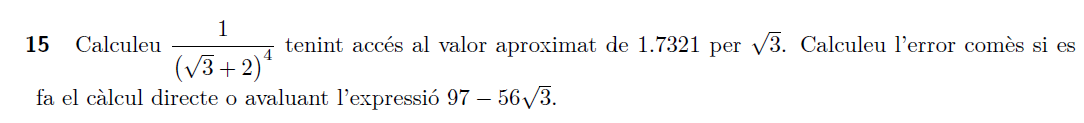

### Convergència mètodes iteratius

 convergència????

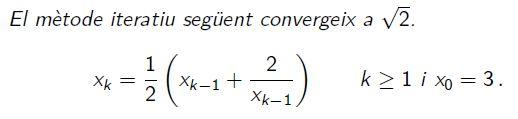

Calculeu els sis primers iterats, no conservem els valors càlculats

x = 3
for k = 1:7
    x = (x+2/x)/2
end

Calculeu els sis primers iterats, totes les iteracions en un vector

% 
format longE
y(1) = 3;
for k = 2:7
    y(k) = (y(k-1)+2/y(k-1))/2;
end
ea = abs(y-sqrt(2));
er = ea / sqrt(2);
R = [y; ea; er]'
T = array2table(R,...
    'VariableNames',{'x_k','ea_k','er_k'})

Calculeu els ¿¿¿tots ???  els iterats

% Totes les iteracions en un vector
y(1) = 3;
k = 2;
while k < 70
    y(k) = (y(k-1)+2/y(k-1))/2;
    k = k+1;
end
ea = abs(y-sqrt(2));
er = ea / sqrt(2);
R = [(1:k-1); y; ea; er]'
T = array2table(R,...
    'VariableNames',{ 'k','x_k','ea_k','er_k'})

# Aritmetica de punt/coma flotant

[Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

[Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

[A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)

format long g
a = 4/3
b = a -1
c= b+b+b
e=1-c

Toby Driscoll (2021). IEEE 754 binary representation (https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation), MATLAB Central File Exchange. Retrieved February 15, 2021.

x = 2
[S,E,F] = ieee754(x)